clear global;
clc;

%% Radar Specifications 
% Frequency of operation = 77 GHz
% Max Range = 200 m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
% Speed of light = 3e8 m/s

%% User Defined Range and Velocity of target
R = 110;     % Target's initial position [m]
v = -20;     % Target's initial velocity [m/s]
 
%% FMCW Waveform Generation
c = 3e8;                 % Speed of light [m/s]
d_res = 1;               % Range resolution [m]
B = c / (2 * d_res);     % Bandwidth
R_max = 200;             % Maximum range [m]
Tchirp = 7.5 * 2 * R_max / c;  % Sweep time for chirp
slope = B / Tchirp;      % Chirp slope

fc = 77e9;               % Operating carrier frequency of Radar [Hz]

Nr = 2084;               % Number of range cells
Nd = 256;                % Number of Doppler cells
t = linspace(0, Nd * Tchirp, Nr * Nd); % Time axis

Tx = zeros(1, length(t));  % Transmitted signal
Rx = zeros(1, length(t));  % Received signal
Mix = zeros(1, length(t)); % Beat signal

r_t = zeros(1, length(t)); % Range covered
td = zeros(1, length(t));  % Time delay

%% Signal Generation and Moving Target Simulation
for i = 1:length(t)
    r_t(i) = R + v * t(i);           % Update range
    td(i) = 2 * r_t(i) / c;          % Time delay
    
    Tx(i) = cos(2 * pi * (fc * t(i) + (slope * t(i)^2) / 2));
    Rx(i) = cos(2 * pi * (fc * (t(i) - td(i)) + (slope * (t(i) - td(i))^2) / 2));
end

Mix = Tx .* Rx;  % Beat signal

%% Adding White Gaussian Noise
noise_std = 0.5; % Standard deviation of the Gaussian noise
gaussian_noise = noise_std * randn(size(Mix)); % Generate Gaussian noise

Mix_noisy = Mix + gaussian_noise; % Add Gaussian noise to the beat signal

%% Butterworth Low-Pass Filter Design
fs = 8000;                      % Sampling frequency [Hz]
f_pass = 1600;                  % Passband frequency [Hz]
f_stop = 1800;                  % Stopband frequency [Hz]
passband_ripple = 0.02;         % Passband ripple [dB]
stopband_attenuation = 50;      % Stopband attenuation [dB]

% Normalize frequencies
Wp = f_pass / (fs / 2);         % Normalized passband
Ws = f_stop / (fs / 2);         % Normalized stopband

% Design Butterworth low-pass filter
[n, Wn] = buttord(Wp, Ws, passband_ripple, stopband_attenuation);
[b, a] = butter(n, Wn, 'low');

% Apply the low-pass filter to the noisy beat signal
Mix_filtered = filter(b, a, Mix_noisy);

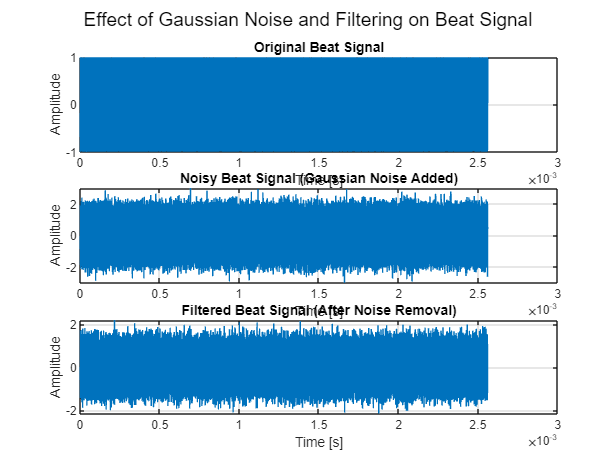

%% Time-Domain Comparison of Signals
figure('Name', 'Time-Domain Signal Comparison');
subplot(3, 1, 1);
plot(t, Mix);
title('Original Beat Signal');
xlabel('Time [s]');
ylabel('Amplitude');
grid on;

subplot(3, 1, 2);
plot(t, Mix_noisy);
title('Noisy Beat Signal (Gaussian Noise Added)');
xlabel('Time [s]');
ylabel('Amplitude');
grid on;

subplot(3, 1, 3);
plot(t, Mix_filtered);
title('Filtered Beat Signal (After Noise Removal)');
xlabel('Time [s]');
ylabel('Amplitude');
grid on;

sgtitle('Effect of Gaussian Noise and Filtering on Beat Signal');

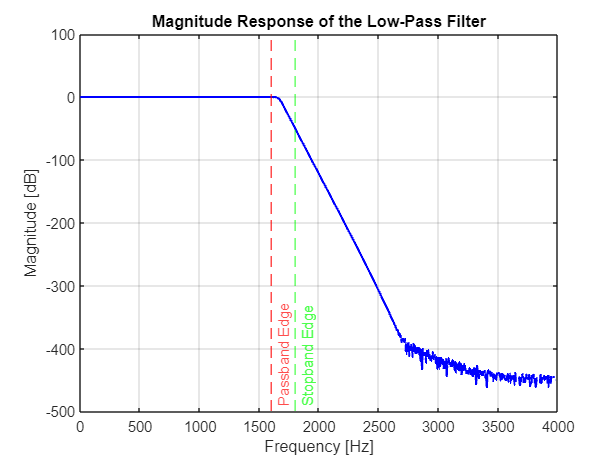

%% Compute the filter's frequency response
[H, freq] = freqz(b, a, 1024, fs);  % Magnitude response of the filter

% Plot the magnitude response (in dB)
figure('Name', 'Filter Frequency Response');
plot(freq, 20*log10(abs(H)), 'b', 'LineWidth', 1.5);
hold on;

% Annotate cutoff frequencies
xline(f_pass, '--r', 'Passband Edge', 'LabelVerticalAlignment', 'bottom', 'LineWidth', 1);
xline(f_stop, '--g', 'Stopband Edge', 'LabelVerticalAlignment', 'bottom', 'LineWidth', 1);

% Add labels and grid
title('Magnitude Response of the Low-Pass Filter');
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
grid on;
hold off;

%% RANGE MEASUREMENT
Mix_reshaped = reshape(Mix_filtered, [Nr, Nd]);

% FFT along the range axis
Y = fft(Mix_reshaped, [], 1);
P = abs(Y ./ Nr);  % Normalize
P1 = P(1:Nr/2+1, :);  % Single-sided spectrum

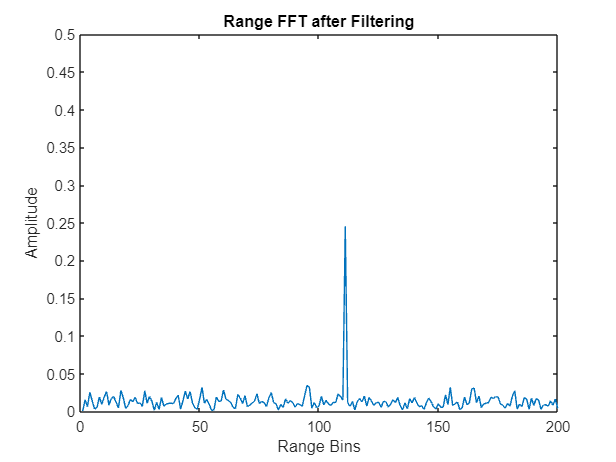

% Plot the FFT output
figure('Name', 'Range from First FFT');
plot(P1(:, 1));
title('Range FFT after Filtering');
xlabel('Range Bins');
ylabel('Amplitude');
axis([0 200 0 0.5]);

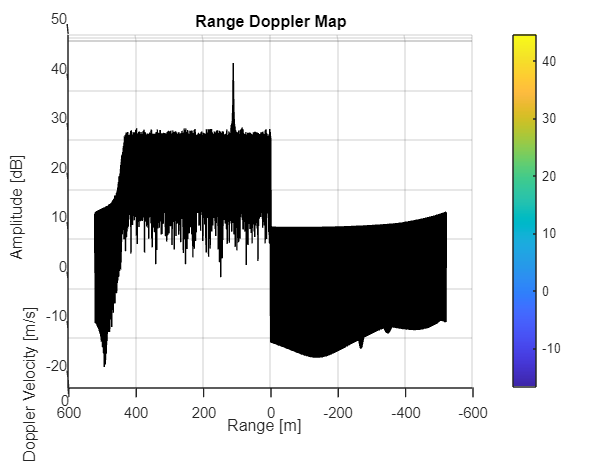

%% RANGE DOPPLER RESPONSE
Mix_reshaped = reshape(Mix_filtered, [Nr, Nd]);
sig_fft2 = fft2(Mix_reshaped, Nr, Nd);   % 2D FFT
sig_fft2 = sig_fft2(1:Nr/2, 1:Nd);
sig_fft2 = fftshift(sig_fft2);
RDM = abs(sig_fft2);
RDM = 10 * log10(RDM);

% Range Doppler Map
doppler_axis = linspace(-100, 100, Nd);
range_axis = linspace(-200, 200, Nr/2) * ((Nr/2) / 400);
figure('Name', '2D FFT output - Range Doppler Map');
surf(doppler_axis, range_axis, RDM);
title('Range Doppler Map');
xlabel('Doppler Velocity [m/s]');
ylabel('Range [m]');
zlabel('Amplitude [dB]');
colorbar;

view([-89.9 -1.1])

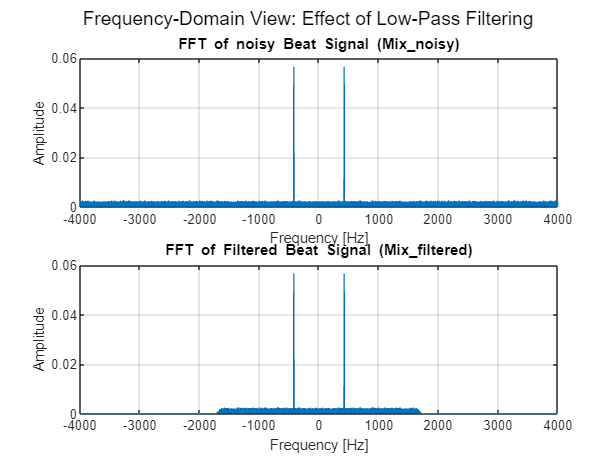

%%%%%%%%%%%%%%% Frequency-Domain Comparison Using FFT

Mix_fft = fft(Mix_noisy);               % FFT of noisy beat signal
Mix_filtered_fft = fft(Mix_filtered); % FFT of filtered beat signal

% Frequency axis for plotting
L = length(t);                    % Signal length
f = linspace(-fs/2, fs/2, L);     % Frequency range (centered at zero)

% Shift FFT for visualization
Mix_fft_shifted = fftshift(abs(Mix_fft) / L);
Mix_filtered_fft_shifted = fftshift(abs(Mix_filtered_fft) / L);

% Plot unfiltered and filtered FFTs side by side
figure('Name', 'Frequency-Domain Comparison');
subplot(2, 1, 1);
plot(f, Mix_fft_shifted);
title('FFT of noisy Beat Signal (Mix\_noisy)');
xlabel('Frequency [Hz]');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(f, Mix_filtered_fft_shifted);
title('FFT of Filtered Beat Signal (Mix\_filtered)');
xlabel('Frequency [Hz]');
ylabel('Amplitude');
grid on;

% Add annotations to highlight noise reduction in the frequency domain
sgtitle('Frequency-Domain View: Effect of Low-Pass Filtering');

%% Signal-to-Noise Ratio Calculation
% Compute SNR for Unfiltered and Filtered Signals in the Time Domain
signal_power = mean(abs(Mix).^2);          % Power of the original beat signal
noise_power = noise_std^2;                % Power of Gaussian noise (standard deviation squared)

SNR_unfiltered = 10 * log10(signal_power / noise_power);
filtered_signal_power = mean(abs(Mix_filtered).^2); % Power of filtered signal
SNR_filtered = 10 * log10(filtered_signal_power / noise_power);

% Display SNR Values
fprintf('SNR (Unfiltered Signal): %.2f dB\n', SNR_unfiltered);

SNR (Unfiltered Signal): 0.01 dB


fprintf('SNR (Filtered Signal): %.2f dB\n', SNR_filtered);

SNR (Filtered Signal): 0.51 dB


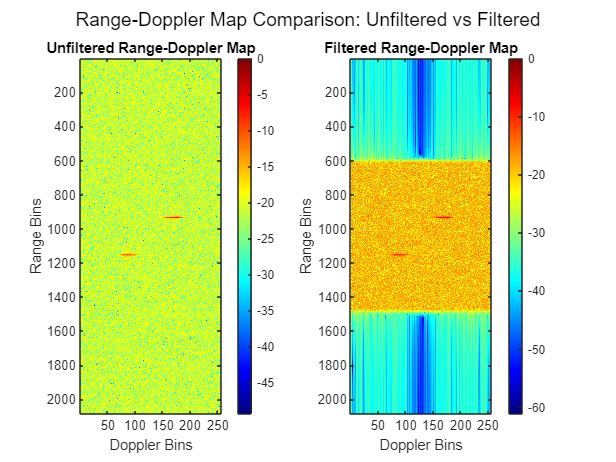

%% Range-Doppler Map Comparison

Mix_reshaped_unfiltered = reshape(Mix, [Nr, Nd]);
Mix_reshaped_filtered = reshape(Mix_filtered, [Nr, Nd]);

% Compute Range-Doppler Maps using 2D FFT
RDM_unfiltered = fft2(Mix_reshaped_unfiltered, Nr, Nd);
RDM_unfiltered = fftshift(abs(RDM_unfiltered)); % Shift zero frequency to center

RDM_filtered = fft2(Mix_reshaped_filtered, Nr, Nd);
RDM_filtered = fftshift(abs(RDM_filtered));

% Normalize and convert to log scale for visualization
RDM_unfiltered_log = 10 * log10(RDM_unfiltered / max(RDM_unfiltered(:)));
RDM_filtered_log = 10 * log10(RDM_filtered / max(RDM_filtered(:)));

% Plot Range-Doppler Maps Side by Side
figure('Name', 'Range-Doppler Map Comparison');
subplot(1, 2, 1);
imagesc(RDM_unfiltered_log);
title('Unfiltered Range-Doppler Map');
xlabel('Doppler Bins');
ylabel('Range Bins');
colorbar;
colormap('jet');

subplot(1, 2, 2);
imagesc(RDM_filtered_log);
title('Filtered Range-Doppler Map');
xlabel('Doppler Bins');
ylabel('Range Bins');
colorbar;
colormap('jet');

% Annotate Comparison
sgtitle('Range-Doppler Map Comparison: Unfiltered vs Filtered');

fprintf('Note: The noise floor appears reduced in the filtered map.\n');

Note: The noise floor appears reduced in the filtered map.


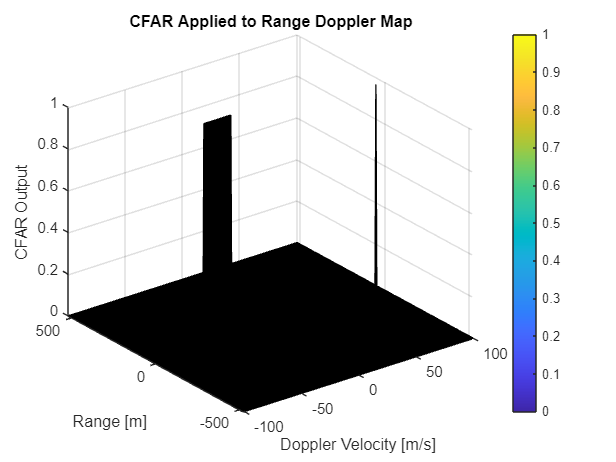

%% CFAR Implementation
Tr = 7; Td = 7;  % Training cells
Gr = 3; Gd = 3;  % Guard cells
offset = 8;      % SNR offset [dB]

% Initialize matrix for CFAR
RDM_truncated = RDM;
RDM_truncated(union(1:Tr+Gr, end-(Tr+Gr-1):end), :) = 0;
RDM_truncated(:, union(1:Td+Gd, end-(Td+Gd-1):end)) = 0;

% CFAR Thresholding
RDM_CFAR = zeros(size(RDM_truncated));
for i = (Tr + Gr + 1):(Nr/2 - (Tr + Gr))
    for j = (Td + Gd + 1):(Nd - (Td + Gd))
        noise_level = sum(sum(db2pow(RDM_truncated(i-(Tr+Gr):i+(Tr+Gr), j-(Td+Gd):j+(Td+Gd)))));
        noise_level = noise_level - sum(sum(db2pow(RDM_truncated(i-Gr:i+Gr, j-Gd:j+Gd))));
        threshold = pow2db(noise_level / ((2*(Tr+Gr)+1) * (2*(Td+Gd)+1) - (2*Gr+1) * (2*Gd+1))) + offset;
        if RDM(i, j) > threshold
            RDM_CFAR(i, j) = 1;
        else
            RDM_CFAR(i, j) = 0;
        end
    end
end
% Plot CFAR output
figure('Name', 'CFAR Output');
surf(doppler_axis, range_axis, RDM_CFAR);
title('CFAR Applied to Range Doppler Map');
xlabel('Doppler Velocity [m/s]');
ylabel('Range [m]');
zlabel('CFAR Output');
colorbar;